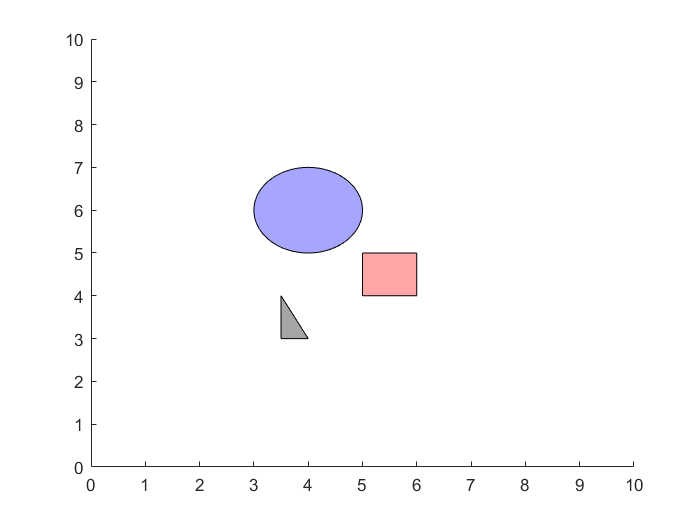

%Samarth Sachan
%190749

%random function is used in program so the path will change everytime the
%user runs the program

clc;
close all
clear all

f1 = figure;

p1 = polyshape([5 5 6 6],[4 5 5 4]);
p3 = polyshape([3.5 4;4 3;3.5 3]);

figure(f1)
axis([0 10 0 10]);
hold on

%plotting circle
p2 = nsidedpoly(1000, 'Center', [4 6], 'Radius', 1);
plot(p2, 'FaceColor', 'blue');

plot (p1,'FaceColor','red'); % square

plot(p3,'FaceColor','black'); % traingle

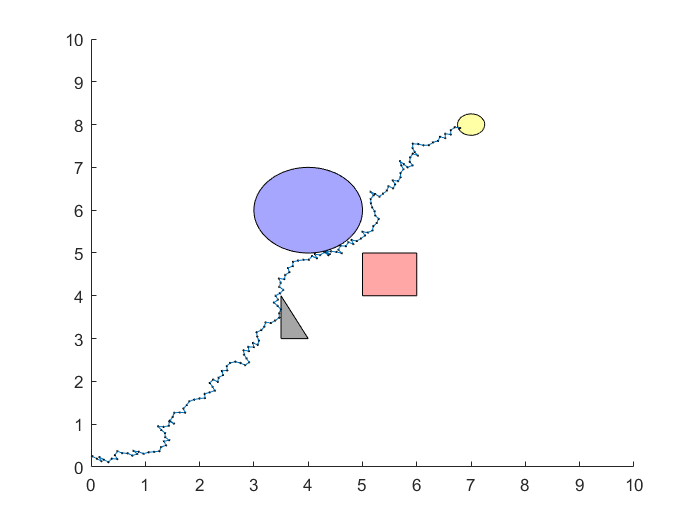



cpoint = [0;0]; % current point (starting point)
gpoint = [7;8]; % goal point marked with a yellow circle


gzone.R = 0.25; % zone area of goal
gzone.center = gpoint;
p4 = nsidedpoly(1000, 'Center', [gpoint(1) gpoint(2)], 'Radius', gzone.R);
plot(p4, 'FaceColor', 'yellow');

stepSize = 0.1;
for i= 1:500
    direction = Random_direction(cpoint,gpoint);
    new_point = cpoint + stepSize*direction;
    
    % checking intersection with circle
    if calcDistance(new_point,[4;6]) <= 1
        continue;
    end
    
    % checking intersection with square
    if (new_point(1)>5 &&  new_point(1)<6 && new_point(2)>4 &&  new_point(2)<5 ) 
        continue;
    end
    
    % checking intersection with traingle
    if  (new_point(2)+2*new_point(1)-11)<=0 && new_point(1)>3.5 &&  new_point(1)<4 && new_point(2)>3 &&  new_point(2)<4
        continue;
    end
    
    
    figure(f1)
    line([cpoint(1),new_point(1)],[cpoint(2),new_point(2)]);
    hold on
    scatter(new_point(1),new_point(2),1,'black')
    cpoint = new_point;
    
    if gzone.R > calcDistance(gzone.center,cpoint)
        break;
    end
    
    pause (0.01);
end

function [distance] = calcDistance(point1 , point2)
%this function calculates the distance between two points
distance = sqrt((point1(1) - point2(1))^2 + (point1(2) - point2(2))^2);
end

function [direction] = Random_direction(cpoint , gpoint)
%this function genrates the random direction towards the goal (-90 degree to 90 degree) 

% generating random theta between -90 to +90
a = -90;
b = 90;
theta = (b-a).*rand(1,1) + a;

goal_direction = gpoint - cpoint;
rotation_matrix = [cosd(theta) sind(theta);...
                   -sind(theta) cosd(theta)];
%rotating the vector               
rand_direction = rotation_matrix*goal_direction;     
% taking unit vector 
direction = 1/sqrt(rand_direction(1)^2 + rand_direction(2)^2) * rand_direction;

end
